# **付録**

**Step1〜Step6はGUILDAの基本的な使用方法です。**

**このファイルでは、追加機能としての実装に関して随時追加していきます。**

# **・ ネットワークの情報の一覧表示**

[Step3_NetProperties.mlx](matlab:open('./Step3_NetProperties.mlx'))ではpower_networkの内部のデータの読み方を開設しましたが、各母線や送電線、機器のデータを一覧表示で見たい場合もあるでしょう。

そういった場合に便利なメソッドを紹介します！

 
net = network.Tutorial3bus;
net.information;

送電線のパラメータ
                  class       bus_number         x          y    phase    tap    parallel
               ___________    __________    ____________    _    _____    ___    ________

    branch1    "branch.pi"      1    2       0.01+0.085i    0     NaN     NaN      "on"  
    branch2    "branch.pi"      2    3      0.017+0.092i    0     NaN     NaN      "on"  




潮流設定/母線のパラメータ
               class        Vabs        Varg        Iabs        Iarg      RealPower    ReactivePower    ApparentPower    PowerFactor    shunt         connected_component            Vequilibrium         Iequilibrium  
            ___________    ______    __________    _______    ________    _________    _____________    _____________    ___________    _____    ______________________________    _________________    ________________

    bus1    "bus.slack"         2    8.8799e-25     1.28

# **・ 各クラスの検索（一覧表表示）**

GUILDAでは系統モデル`(power_network)`クラスを構成する要素として大きく分けて４つのクラスが存在します。

- `bus`：母線クラス

- `branch`：送電線クラス

- `component`：機器クラス

- `controller`：制御器クラス

各クラスの情報については、[Step3_NetProperties.mlx](matlab:open('./Step3_NetProperties.mlx'))で解説しました。

ここでは、これらのクラスから派生したクラスを検索する方法を紹介します。

試しに以下のドロップダウンを選択してみてください！

cls = "component";
class_dictionary(cls);

 
component class：
       Link　　　class tree
 [help], [doc]     component
 [help], [doc]       ┣━ component.GFM.Inverter


# **・ 新しい子クラスの作成**

Step1~Step6を通して、GUILDAの一通りの作業を解説しました。

ここでは、その応用編として新しい機器モデルや制御器モデルを実装する方法を解説します。

新たな機器・制御器モデルを実装する場合componentクラスやcontrollerクラスを継承したクラスを作成する訳ですが、その際実装すべきメソッドやプロパティ等が定められています。そのため、これらのルールに則って作成する必要があります。

GUILDAには、これらのルールに従うように定義すべきメソッド等を書いた雛形を作成する関数があります。

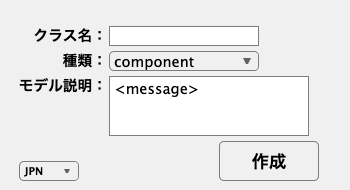

 
defineClass

　関数を実行するとUIが起動します。

- クラス名：名前は英文字列で特殊文字を使用しない形で指定してください。実装するモデルを指し示すような名前を推奨します。

- クラスの種類：作成するモデルが機器か制御器か送電線かに応じて、それぞれcomponent, controller, branchを選択してください。

- モデルの説明：そのモデルの説明を追加

    上記３点を入力し終えたら「作成」ボタンを押してください。

    保存するディレクトリを選択すると自動的にファイルが生成されます。